# 3.8. Магнитная цепь

#### Теорема о циркуляции для тороидального соленоида с малым воздушным зазором delta

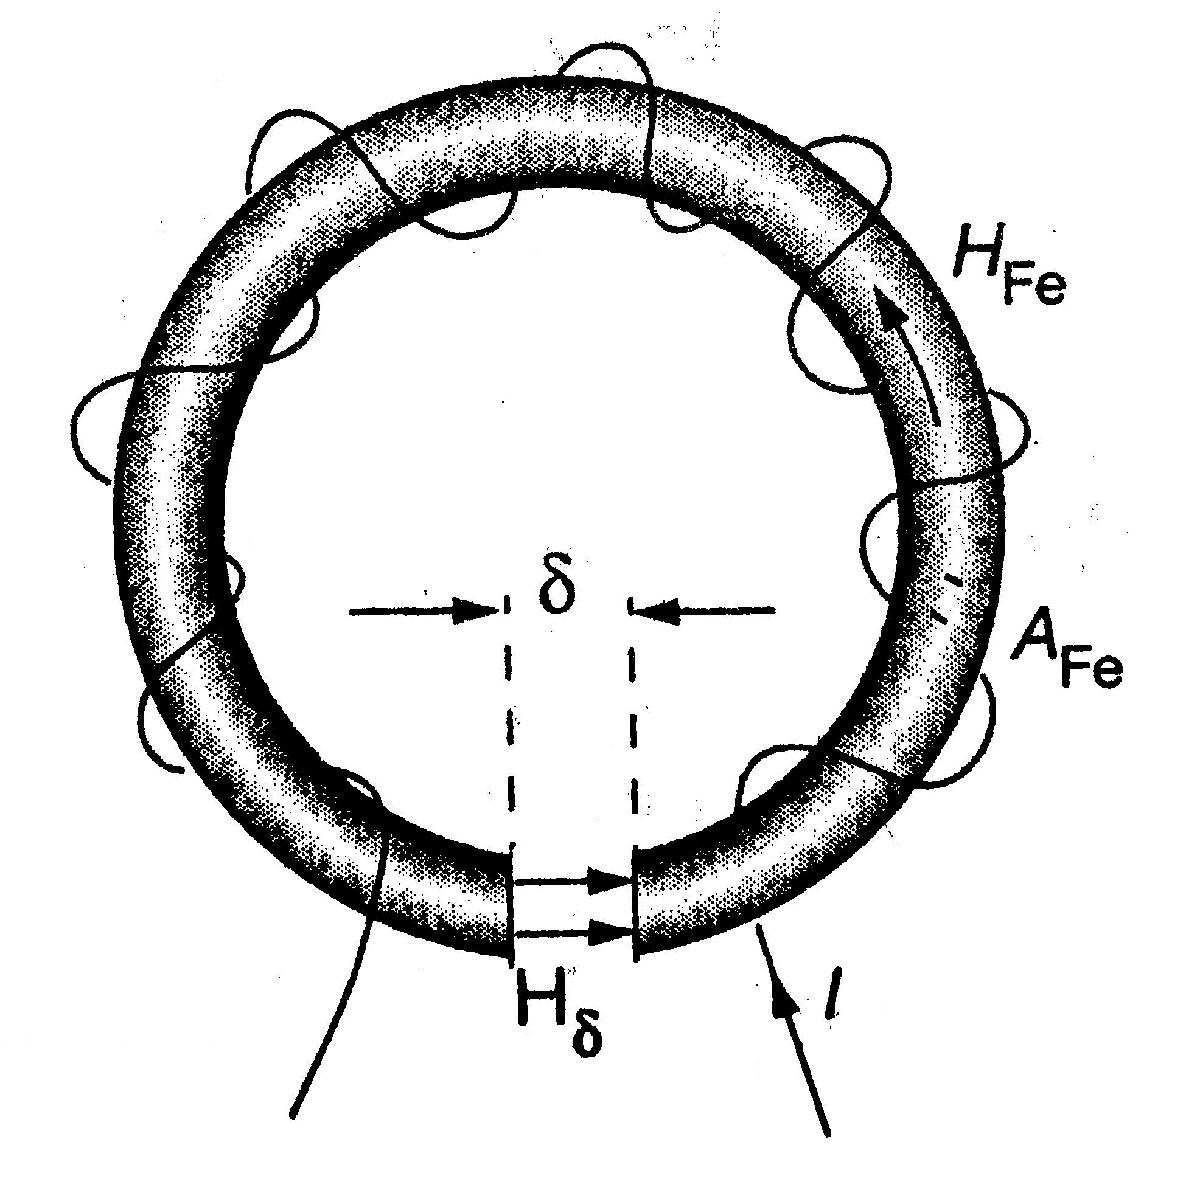

clear 
syms H_Fe L H_delta delta N I
H_Fe*L+H_delta*delta==N*I

$$ans = H_{\delta }\,\delta +H_{\mathrm{Fe}}\,L=\text{I}\,N$$

% L = длина соленоида

Намагниченное поле в соленоиде, утечками можно пренебречь

syms M_Fe
H_Fe==N*I/(L+delta)-delta/(L+delta)*M_Fe

$$ans = H_{\mathrm{Fe}}=\frac{\text{I}\,N}{L+\delta }-\frac{M_{\mathrm{Fe}}\,\delta }{L+\delta }$$

delta/(L+delta)  % = коэффициент размагничевания

$$ans = \frac{\delta }{L+\delta }$$

Магнитный поток

syms Phi_B B_Fe A_Fe B_delta A_delta
Phi_B==B_Fe*A_Fe==B_delta*A_delta

$$ans = \left(\Phi_{B}=A_{\mathrm{Fe}}\,B_{\mathrm{Fe}}\right)=A_{\delta }\,B_{\delta }$$

% A = площадь сечения

*Пример 1.* 

syms B_delta mu mu0 N I L delta
B_delta==mu*mu0*(N*I)/(L-delta+mu*delta)

$$ans = B_{\delta }=\frac{\text{I}\,N\,\mu \,\mu_{0}}{L-\delta +\delta \,\mu }$$

*Пример 2.* Постоянный магнит (I=0)

H_Fe*L+H_delta*delta==0

$$ans = H_{\delta }\,\delta +H_{\mathrm{Fe}}\,L=0$$

B_Fe==-H_Fe*mu0*L/delta*A_delta/A_Fe

$$ans = B_{\mathrm{Fe}}=-\frac{A_{\delta }\,H_{\mathrm{Fe}}\,L\,\mu_{0}}{A_{\mathrm{Fe}}\,\delta }$$

#### Магнитное сопротивление и магнитная проводимость магнитопровода длины L и площади A

syms R_m L mu mu0 A Lambda
R_m==L/(mu*mu0*A)

$$ans = R_{m}=\frac{L}{A\,\mu \,\mu_{0}}$$

Lambda==1/R_m

$$ans = \Lambda =\frac{1}{R_{m}}$$

#### "Закон Ома" для магнитной цепи

N*I==R_m*Phi_B

$$ans = \text{I}\,N=\Phi_{B}\,R_{m}$$

#### Магнитная "полярная масса" внутри замкнутой поверхности S


$$Q_m =\oint r_S \mathit{\mathbf{H}}\;\mathbf{dS}$$


syms Q_m r(S) H S
Q_m==int(r*H,S)

$$ans(S) = Q_{m}=\int H\,r\left(S\right)\mathrm{d}S$$

#### Магнитная "полярная плотность"


$$\rho_m =-\mathrm{div}\;\mathit{\mathbf{M}}$$


syms rho_m M div(x)
rho_m==-div(M)

$$ans = \rho_{m}=-\mathrm{div}\left(M\right)$$